% set index = 2 (sum PHI) in MC_import
MC_import

ans =     13     1


ans =     15   468


ans =     16    14


ans =     14     1


ans =     16     5


ans =     18     3



exp_data = readtable("Subjective score.xlsx", 'Sheet','Diff Intervention');
exp_solv = readtable("Subjective score.xlsx", 'Sheet','The number of Responses');


member = 1:20;
member([11, 14]) = [];
member(15) = [];

exp_solv = table2array(exp_solv(member, 2));

% active - control - passive
Excitement = table2array(exp_data(member, 3:5));
Efforts = table2array(exp_data(member, 6:8));
Concentration = table2array(exp_data(member, 9:11));
Tiredness = table2array(exp_data(member, 12:14));
Irritation = table2array(exp_data(member, 15:17));
Boring = table2array(exp_data(member, 18:20));
Annoying = table2array(exp_data(member, 21:23));


**Easy - Moderate correlation**

member2 = 1: 18;
member2(15) = [];

b = Excitement + Efforts + Tiredness;
c = Irritation + Boring;

[s, p]  =corr(b(:, 2)-b(:, 1), mean(control_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = 0.1248

p = 0.6331

[s, p]  =corr(c(:, 2)-c(:, 1), mean(control_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = 0.6229

p = 0.0076

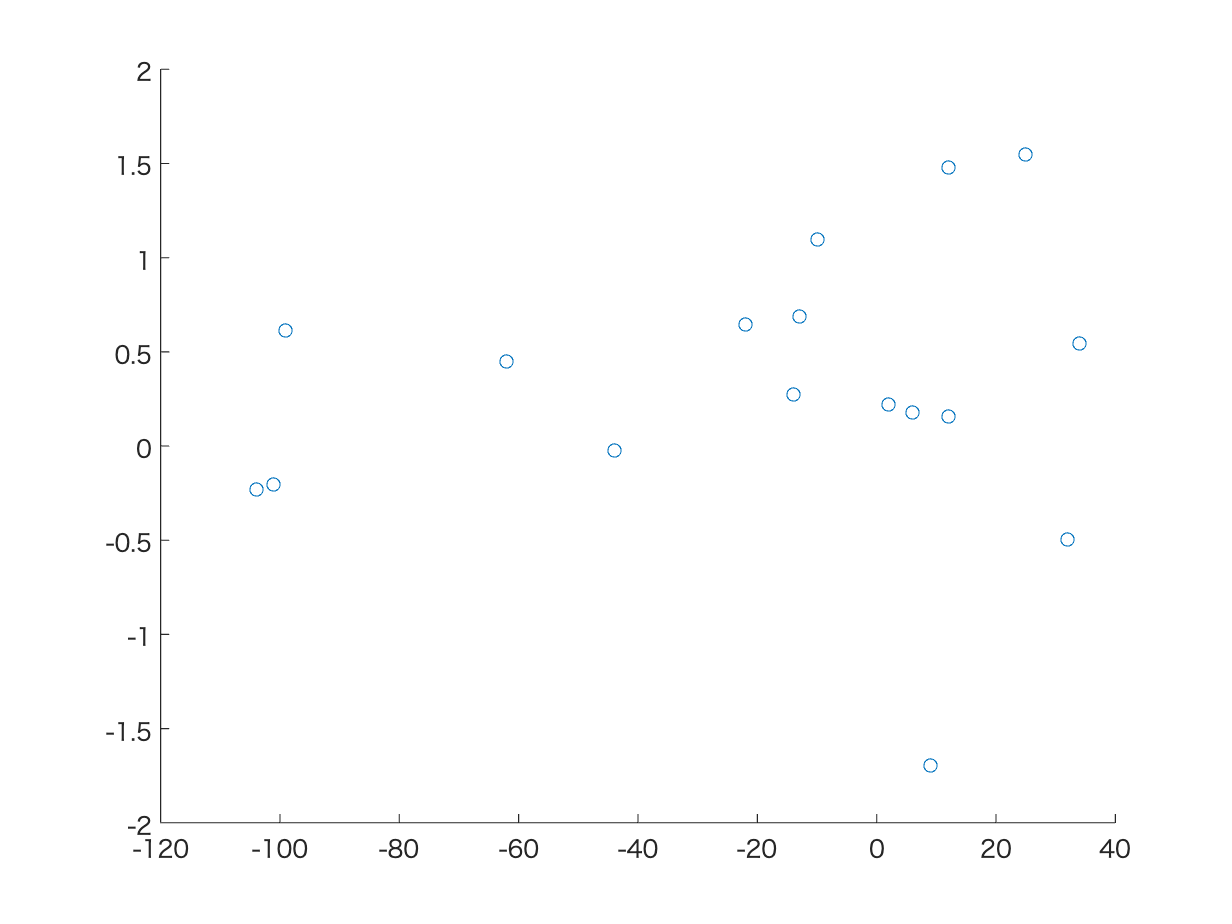


scatter(b(:, 2)-b(:, 1), mean(control_PHI(member2, time1:time2)...
    - active_PHI(member2, time1:time2),2))

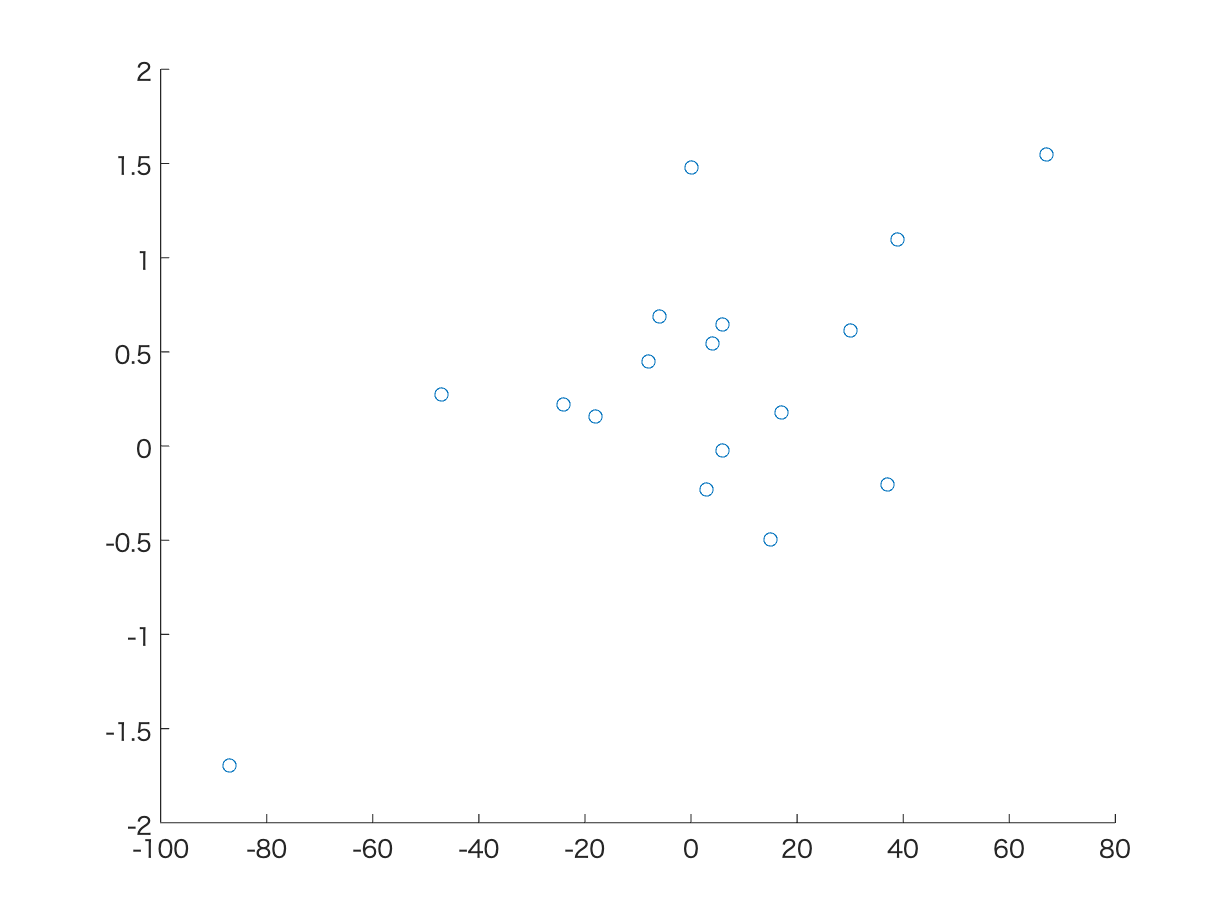

scatter(c(:, 2)-c(:, 1), mean(control_PHI(member2, time1:time2)...
    - active_PHI(member2, time1:time2),2))

**Difficult - Moderate correlation**

b = Excitement + Efforts + Tiredness + Concentration;
c = Irritation + Boring + Annoying;

[s, p]  =corr(b(:, 3)-b(:, 1), mean(passive_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = 0.4330

p = 0.0825

[s, p]  =corr(c(:, 3)-c(:, 1), mean(passive_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = -0.5305

p = 0.0285

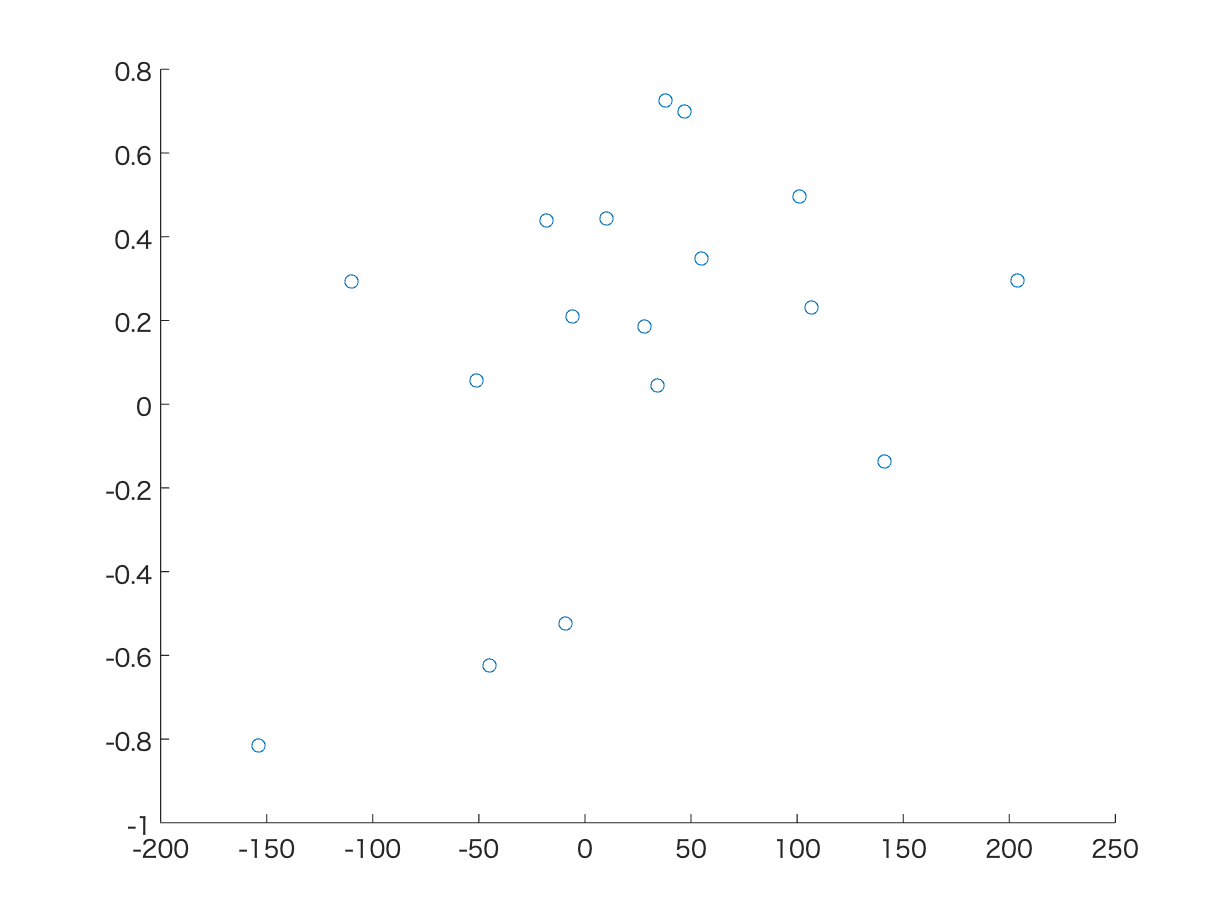



scatter(b(:, 3)-b(:, 1), mean(passive_PHI(member2, time1:time2)...
    - active_PHI(member2, time1:time2),2))

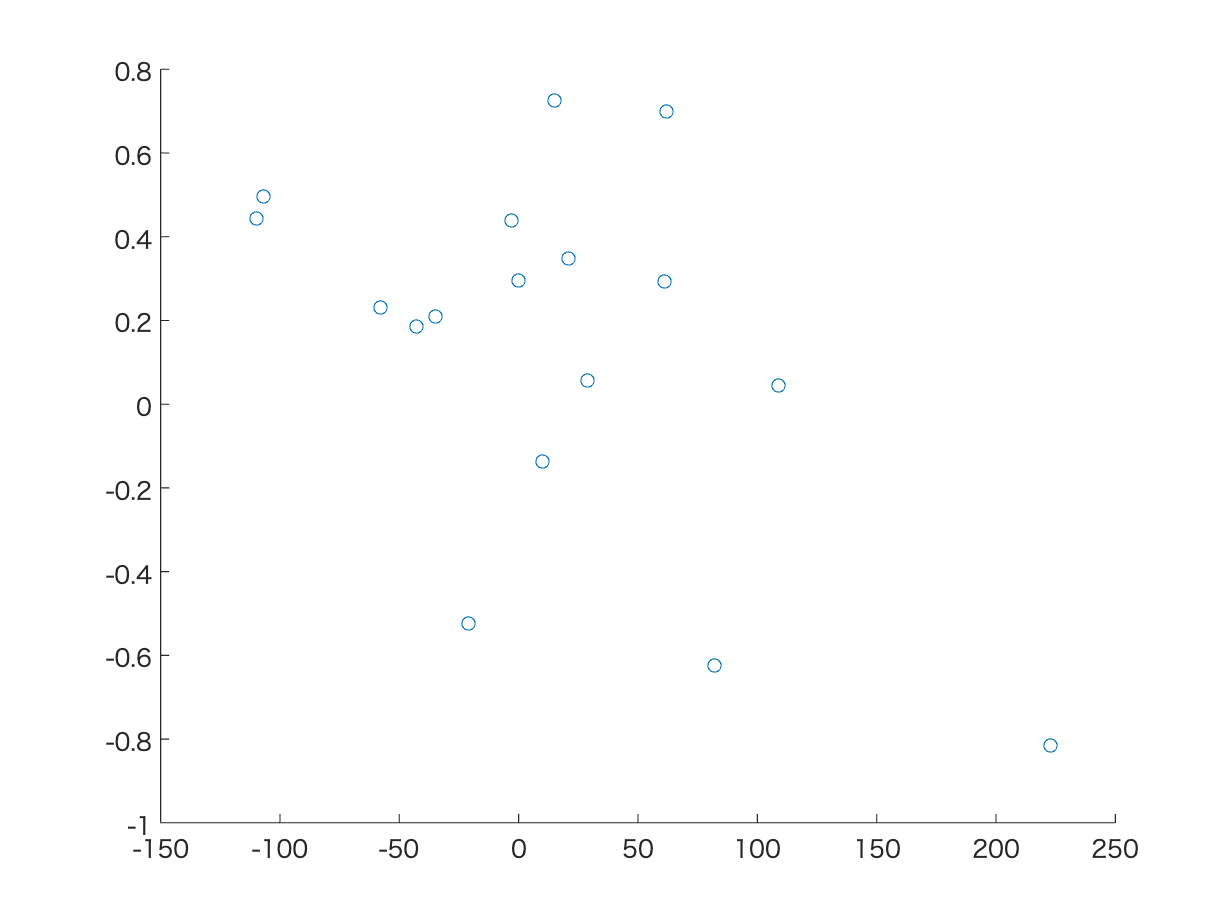

scatter(c(:, 3)-c(:, 1), mean(passive_PHI(member2, time1:time2)...
    - active_PHI(member2, time1:time2),2))

**Easy - Moderate correlation : each condition**


pvalue = zeros(7, 2);
corr_value = zeros(7, 2);

[s, p]  =corr(Excitement(:, 2)-Excitement(:, 1), mean(control_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = -0.0414

p = 0.8747

pvalue(1,1) = p;
corr_value(1,1) = s;

[s, p]  =corr(Efforts(:, 2)-Efforts(:, 1), mean(control_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = 0.0558

p = 0.8315

pvalue(2,1) = p;
corr_value(2,1) = s;

[s, p]  =corr(Concentration(:, 2)-Concentration(:, 1), mean(control_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = -0.2498

p = 0.3336

pvalue(3,1) = p;
corr_value(3,1) = s;

[s, p]  =corr(Tiredness(:, 2)-Tiredness(:, 1), mean(control_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = 0.1954

p = 0.4523

pvalue(4,1) = p;
corr_value(4,1) = s;

[s, p]  =corr(Irritation(:, 2)-Irritation(:, 1), mean(control_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = 0.3453

p = 0.1746

pvalue(5,1) = p;
corr_value(5,1) = s;

[s, p]  =corr(Boring(:, 2)-Boring(:, 1), mean(control_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = 0.5652

p = 0.0181

pvalue(6,1) = p;
corr_value(6,1) = s;

[s, p]  =corr(Annoying(:, 2)-Annoying(:, 1), mean(control_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = 0.2902

p = 0.2585

pvalue(7,1) = p;
corr_value(7,1) = s;

**Difficult - Moderate correlation : each condition**

[s, p]  =corr(Excitement(:, 3)-Excitement(:, 1), mean(passive_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = 0.4426

p = 0.0752

pvalue(1,2) = p;
corr_value(1,2) = s;

[s, p]  =corr(Efforts(:, 3)-Efforts(:, 1), mean(passive_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = 0.2122

p = 0.4137

pvalue(2,2) = p;
corr_value(2,2) = s;

[s, p]  =corr(Concentration(:, 3)-Concentration(:, 1), mean(passive_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = 0.1736

p = 0.5053

pvalue(3,2) = p;
corr_value(3,2) = s;

[s, p]  =corr(Tiredness(:, 3)-Tiredness(:, 1), mean(passive_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = 0.3613

p = 0.1542

pvalue(4,2) = p;
corr_value(4,2) = s;

[s, p]  =corr(Irritation(:, 3)-Irritation(:, 1), mean(passive_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = -0.4030

p = 0.1087

pvalue(5,2) = p;
corr_value(5,2) = s;

[s, p]  =corr(Boring(:, 3)-Boring(:, 1), mean(passive_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = -0.5166

p = 0.0337

pvalue(6,2) = p;
corr_value(6,2) = s;

[s, p]  =corr(Annoying(:, 3)-Annoying(:, 1), mean(passive_PHI(member2, time1:time2),2)...
    - mean(active_PHI(member2, time1:time2),2))

s = -0.3893

p = 0.1225

pvalue(7,2) = p;
corr_value(7,2) = s;


T = table(["Exitement";"Efforts";"Concentration";"Tired";"Irritation";"Boring";"Annoying"], corr_value(:, 1), pvalue(:,1), corr_value(:, 2), pvalue(:,2));
T.Properties.VariableNames = ["Item","Easy_Cor","Easy_Pvalue","Difficult_Cor", "Difficult_Pvalue"];
T

T = 7×5 table
         Item          Easy_Cor     Easy_Pvalue    Difficult_Cor    Difficult_Pvalue
    _______________    _________    ___________    _____________    ________________

    "Exitement"        -0.041395      0.87466         0.44262           0.075211    
    "Efforts"           0.055807      0.83153         0.21215            0.41366    
    "Concentration"     -0.24981      0.33355         0.17357            0.50528    
    "Tired"              0.19539      0.45233         0.36129            0.15421    
    "Irritation"          0.3453      0.17464          -0.403            0.10872    
    "Boring"             0.56516     0.018074        -0.51658           0.033743    
    "Annoying"           0.29022      0.25847         -0.3893            0.12246    


%writetable(T, "each_item_correlation_" + num2str(interval) + ".csv");